# **demo08 of Im2mesh package**

demo08 - Select phases for meshing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com   [Project website](https://github.com/mjx888/im2mesh)   [List of demo](https://mjx888.github.io/im2mesh_demo_html/demo_list.html)

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package. No need to install any MATLAB toolboxes when running this demo.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Import image & generate mesh

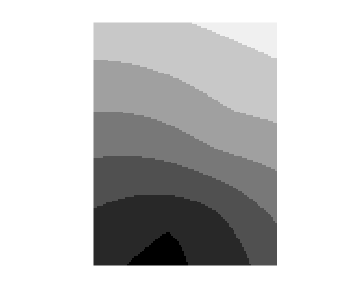

im = imread('Phases.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Show the grayscale levels in the image.

intensity = unique( im ); 
intensity

intensity = 7×1 uint8 column vector
     0
    40
    80
   120
   160
   200
   240


There're 7 phases. 

Let's generate mesh using the default setting.

[ vert, tria, tnum ] = im2mesh( im );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          3                 71                100
          8                 90                179


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                131                100
         10                142                586
         12                142                600


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------



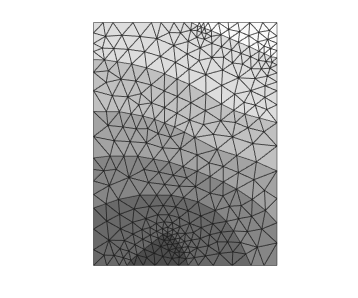

plotMeshes( vert, tria, tnum )

## Select phases for meshing

However, we don't need some of the phases in the image. Those phases may be air voids or background. We don't want them to show up in the finite element meshes.

Function im2mesh support phase selection for meshing. We need to assign a index vector to opt.select_phase. I'll show you how to do that. 

We knew that the image has the following grayscales.

intensity

intensity = 7×1 uint8 column vector
     0
    40
    80
   120
   160
   200
   240


For example, we are interested in the grayscale: 40, 80, 120, 200, 240. We don't want grayscle of 0 and 160. Let's use the following operation to obtain the index vector for opt.select_phase.

grayscale_we_like = [ 40, 80, 120, 200, 240 ]';
ind_vec = find( ismember(intensity, grayscale_we_like) );

% ind_vec is the index vector we need
ind_vec

ind_vec =      2
     3
     4
     6
     7


Let's generate mesh.

opt = [];                       % reset opt
opt.select_phase = ind_vec;     % assign index vector to opt.select_phase
[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          3                 67                 76
          8                 83                140


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                119                 76
         10                130                462
         12                130                474


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                  0                470



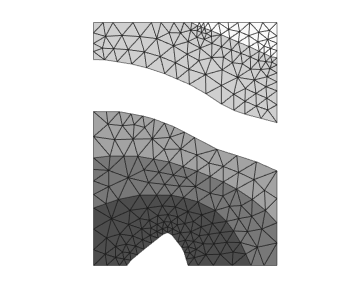

plotMeshes( vert, tria, tnum )

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo